# Opgave 3

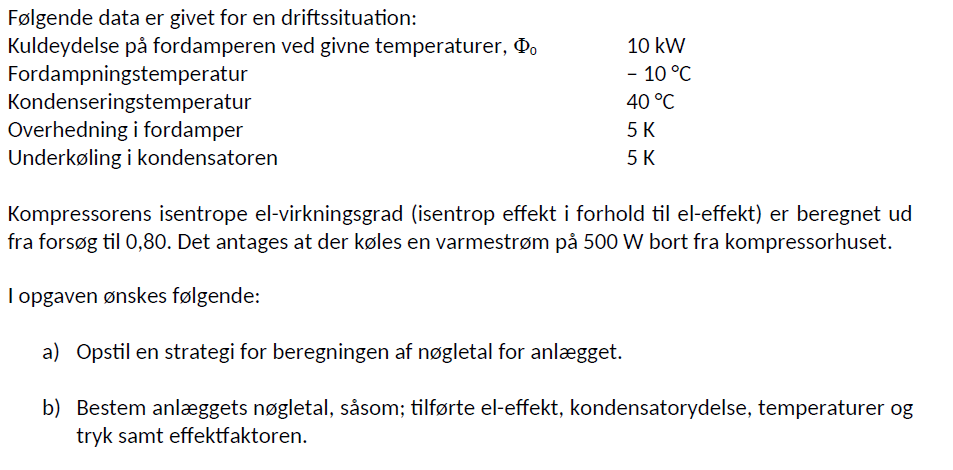

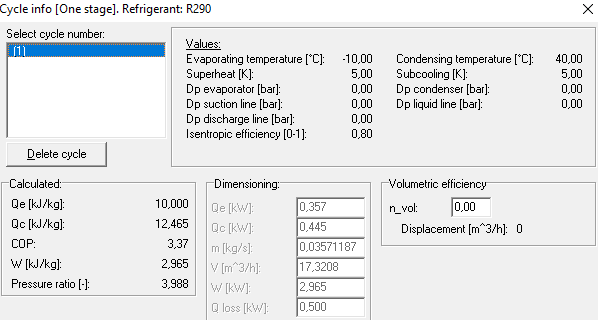

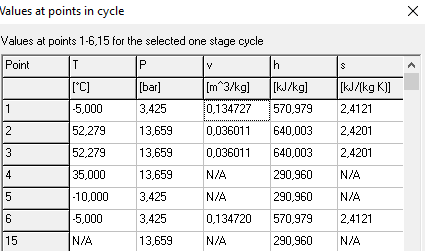

clc; clear all;
u = symunit;

% Info fra opgaven
kompressortab = 0.5 * u.kW;                 % Tab til omgivelser
Phi_41 = 10 * u.kW;         % Kuldeydelse på fordamperen
eta_komp = 0.8;                             % Isentrope el-virkningsgrad


h1 = 570.979 * u.kJ/u.kg;   % Entalpi i pkt 1
h2 = 640.003 * u.kJ/u.kg;   % Entalpi i pkt 2
h3 = 290.960 * u.kJ/u.kg;   % Entalpi i pkt 3
h4 = h3;                    % Entalpi i pkt 4


%% Opgave a og b %%

% Kompressor og specfik varmestrøm fra 4-1
q_41 = h1 - h4;

q_m = Phi_41/q_41;
q_m = vpa(unitConvert(q_m,"SI"),3)

$$q\_m = 0.0357\,\frac{\mathrm{kg}}{s}$$


% Tilførte eleffekt
h2s = 634 * u.kJ/u.kg;

wt_12 = (h2s - h1)/eta_komp;
el_effekt = wt_12*q_m;
el_effekt = vpa(unitConvert(el_effekt, u.kW), 3)

$$el\_effekt = 2.81\,\mathrm{kW}$$


% dKondensatorydelse
pkond = q_m * (h2 - h3);
pkond = vpa(unitConvert(pkond, u.kW), 3)

$$pkond = 12.5\,\mathrm{kW}$$


% COP - effektfaktor
COP = (Phi_41 - kompressortab)/el_effekt;
COP = vpa(COP, 3)

$$COP = 3.38$$



%% Opgave c og d %%
eta_V = 0.85;                % Volumetrisk virkningsgrad
V = 17.3208 * u.m^3/u.h;      % Volumenstrøm fra coolpack
v1 = 0.134727 * u.m^3/u.kg;  % Specifik volumen


q_Vs = V/eta_V;
q_Vs = vpa(unitConvert(q_Vs,u.kg/u.h),3) % Slagvolumenstrøm

$$q\_Vs = 20.4\,\frac{m^{3}}{h}$$



Phi_0 = (q_Vs*eta_V/v1) * (h1 - h4) - kompressortab;
Phi_0 = vpa(unitConvert(Phi_0, u.kW), 3)

$$Phi\_0 = 9.5\,\mathrm{kW}$$



COP = vpa(unitConvert(Phi_0/el_effekt, "SI"), 3)

$$COP = 3.38$$

deltaT = 18*u.K;
V1 = 1500*u.L;
V2 = 1.5 * u.m^3

$$V2 = \frac{3}{2}\,m^{3}$$

cp = 1.004 * u.kJ/(u.kg*u.K);
rho = 1.293 * u.kg/u.m^3;

m = rho * V2

$$m = \frac{3879}{2000}\,\mathrm{kg}$$


energi = m*cp*deltaT;
energi = vpa(unitConvert(energi, u.kJ), 3)

$$energi = 35.1\,\mathrm{kJ}$$


delta_t = energi/Phi_0;
delta_t = vpa(unitConvert(delta_t, "SI"), 3)

$$delta\_t = 3.69\,s$$